**This live script is set to test an algorithm based on colore Threshloder generated function**

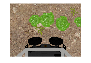

% read the image
%Image = imread("left_noweed_sample.png");
Image = imageList{5};
% Show the image before applying the filter
figure;
imshow(Image);
title("The image");

**Get only weeds**

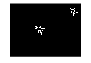

[Result, RGBResult] = colorMask(Image);

% Find connected components in the binary mask
CC = bwconncomp(Result);

% Calculate the area of each connected component
areas = cellfun(@numel, CC.PixelIdxList);

% Threshold to remove small objects (adjust the value as needed)
minAreaThreshold = 40; % Minimum area to consider as a detected object

% Initialize a new binary mask for the detected objects
Result = false(size(Result));

% Filter out small objects and retain only the large ones (detected weeds)
for i = 1:CC.NumObjects
    if areas(i) >= minAreaThreshold
        Result(CC.PixelIdxList{i}) = true;
    end
end

% Optionally, remove small holes within the detected objects
Result = imfill(Result, 'holes');

figure;
imshow(Result);
title("Weeds");

**Locate Weeds**

% Apply morphological dilation to merge nearby white pixels
se = strel('disk', 5); % Adjust the radius as per your requirements
Result = imdilate(Result, se);

CC = bwconncomp(Result);
% Get the number of instances (connected components)
numInstances = CC.NumObjects;
disp(numInstances);

     2



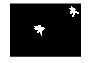

% Initialize a cell array to store the (u,v) coordinates for each instance
instanceCoordinates = cell(numInstances, 1);

% Iterate over each instance and calculate its centroid (u,v) coordinates
for i = 1:numInstances
    % Get the pixel indices for the current instance
    pixelIndices = CC.PixelIdxList{i};
    
    % Convert linear indices to (u,v) coordinates
    [u, v] = ind2sub(size(Result), pixelIndices);
    
    % Calculate the centroid coordinates
    centroidU = mean(u);
    centroidV = mean(v);
    
    % Store the centroid coordinates in the cell array
    instanceCoordinates{i} = [centroidU, centroidV];
end

figure;
imshow(Result);
title("Weeds");

**Project Points into the camera frame**

% The projection matrix come from camera_calibrator
projectionMatrix = [245.698318 0.0 318.613910 0.0; 0.0 253.301102 243.929716 0.0; 0.0 0.0 1.0 0.0];

% Define the (u,v) coordinates of the detected objects
u = instanceCoordinates{1}(1); 
v = instanceCoordinates{1}(2);

% Create homogeneous coordinates
points2D = [u, v, ones(size(u))]; % Or [u, v, 1]

% Apply inverse projection to obtain (x,y,z) coordinates
%points3D = (inv(projectionMatrix) * points2D')'; 
% Considere using A\B instead of inv(A)*B
points3D = (projectionMatrix\points2D');

% Extract (x,y,z) coordinates
x = points3D(1);
y = points3D(2);
z = points3D(3);
position = [x y z];
% Display the (x, y, z) coordinates
disp(position);

   -0.3422    0.0932    1.0000

